opts = delimitedTextImportOptions("NumVariables", 29);
opts.DataLines = [2, Inf];
opts.Delimiter = ",";
opts.VariableNames = ["FilePath", "ID", "AuthorsNote", "StrideSpeed", "StrideLengthFR", "StepLengthFR", "StepWidthFR", "StrideLengthFL", "StepLengthFL", "StepWidthFL", "StrideLengthBR", "StepLengthBR", "StepWidthBR", "StrideLengthBL", "StepLengthBL", "StepWidthBL", "TemporalSymmetryF", "TemporalSymmetryB", "DutyFactorF", "DutyFactorB", "AngularVelocity", "NoseLateralDisplacementBR", "NoseLateralDisplacementPhaseOffsetBR", "TailLateralDisplacementBR", "TailLateralDisplacementPhaseOffsetBR", "StrideCountPerFrameFR", "StrideCountPerFrameFL", "StrideCountPerFrameBR", "StrideCountPerFrameBL"];
opts.VariableTypes = ["string", "double", "categorical", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";
opts = setvaropts(opts, "FilePath", "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["FilePath", "AuthorsNote"], "EmptyFieldRule", "auto");
results = readtable("C:\Users\jxcheng\OneDrive - Boston University\Documents\Andrew Research Data\results.csv", opts)

results = 96×29 table
                                                      FilePath                                                        ID      AuthorsNote      StrideSpeed    StrideLengthFR    StepLengthFR    StepWidthFR    StrideLengthFL    StepLengthFL    StepWidthFL    StrideLengthBR    StepLengthBR    StepWidthBR    StrideLengthBL    StepLengthBL    StepWidthBL    TemporalSymmetryF    TemporalSymmetryB    DutyFactorF    DutyFactorB    AngularVelocity    NoseLateralDisplacementBR    NoseLateralDisplacementPhaseOffsetBR    TailLateralDisplacementBR    TailLateralDisplace

clear opts

opts = spreadsheetImportOptions("NumVariables", 6);
opts.Sheet = "Genotype";
opts.DataRange = "A2"; % open-ended: reads to the end of the sheet, so new animals are picked up
opts.VariableNames = ["Tag", "Sex", "Genotype", "DOB", "Month", "Injections"];
opts.VariableTypes = ["double", "categorical", "categorical", "datetime", "datetime", "datetime"];
opts = setvaropts(opts, ["Sex", "Genotype"], "EmptyFieldRule", "auto");

genotype = readtable("NP recording file list.xlsx", opts, "UseExcel", false);

clear opts

results{:, 4} = -results{:, 4}.*100;
results{:, [26 27 28 29]} = results{:, [26 27 28 29]}.*100;
results{:, 19} = 100 - (results{:, 19} + results{:, 20}) ./ 2; % combined back duty factor into front

% Metric columns are captured before the join, which appends the sheet's own columns.
vars = results.Properties.VariableNames(4:end);

vars = vars(:, [1 16 23 24 25 26]); % isolate specific vars (stride speed, duty factor, stride count)

data = innerjoin(results, genotype, "LeftKeys", "ID", "RightKeys", "Tag");
data.AuthorsNote = categorical(data.AuthorsNote);
data.AuthorsNote = removecats(data.AuthorsNote, "Training video");
data.AuthorsNote = reordercats(data.AuthorsNote, ["60 DPI", "150 DPI", "LDOPA"]);

fprintf("Genotype join: %d of %d result row(s) matched a tag.\n", height(data), height(results));

Genotype join: 96 of 96 result row(s) matched a tag.


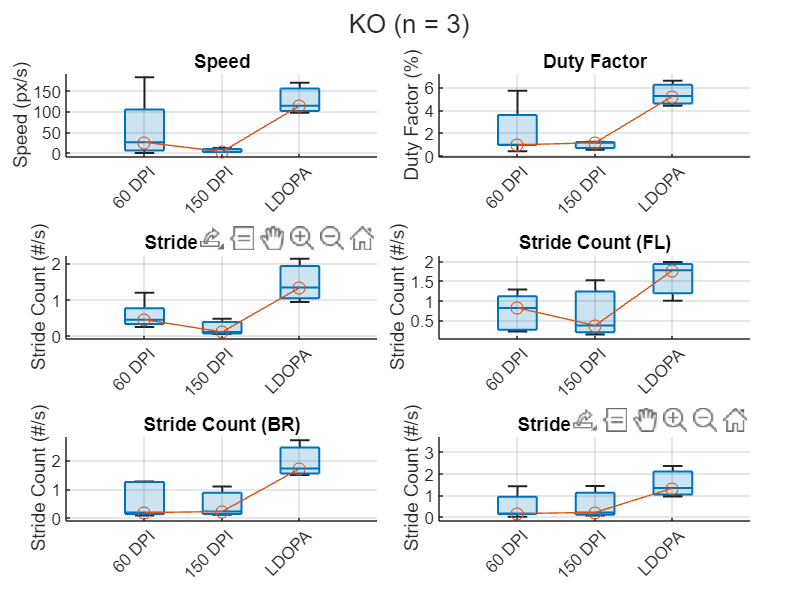

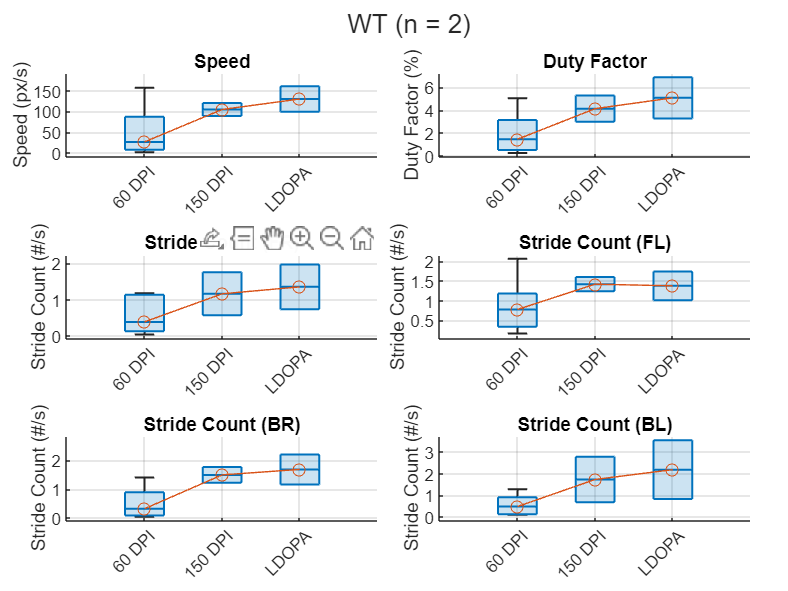


genotypes = categories(removecats(data.Genotype));
metricColors = lines(numel(vars));

varYLim = cell(size(vars));

for i = 1:numel(vars)
    y = data{~isundefined(data.AuthorsNote), vars{i}};
    ymin = min(y, [], "omitnan");
    ymax = max(y, [], "omitnan");

    pad = 0.05 * (ymax - ymin);
    if pad == 0
        pad = 1;
    end

    varYLim{i} = [ymin - pad, ymax + pad];
end

for k = 1:numel(genotypes)
    inGenotype = data.Genotype == genotypes{k};
    group = removecats(data.AuthorsNote(inGenotype));

    figure
    tiledlayout("flow", "TileSpacing", "compact", "Padding", "compact")

    for i = 1:numel(vars)
        nexttile

        b = boxchart(group, data{inGenotype, vars{i}});

        ylim(varYLim{i})   % same y-axis for this metric across genotypes

        xtickangle(45)
        grid on

        if vars{i} == "StrideSpeed", ylabel("Speed (px/s)"), title("Speed"); end
        if vars{i} == "DutyFactorF", ylabel("Duty Factor (%)"), title("Duty Factor"); end
        if vars{i} == "StrideCountPerFrameFR", ylabel("Stride Count (#/s)"), title("Stride Count (FR)"); end
        if vars{i} == "StrideCountPerFrameFL", ylabel("Stride Count (#/s)"), title("Stride Count (FL)"); end
        if vars{i} == "StrideCountPerFrameBR", ylabel("Stride Count (#/s)"), title("Stride Count (BR)"); end
        if vars{i} == "StrideCountPerFrameBL", ylabel("Stride Count (#/s)"), title("Stride Count (BL)"); end

        catNames = categories(group);
        medians = zeros(size(catNames));
    
        for c = 1:numel(catNames)
            % Logical index for current category
            catIdx = (group == catNames{c});
            % Compute median omitting NaN values
            medians(c) = median(data{inGenotype & (data.AuthorsNote == catNames{c}), vars{i}}, 'omitnan');
        end

        % 3. Overlay the median line across the categorical x-axis
        hold on
        plot(1:numel(catNames), medians, '-o');
        hold off
    end

    numDrugWindow = [sum(inGenotype & data.AuthorsNote == "150 DPI"), ...
        sum(inGenotype & data.AuthorsNote == "LDOPA")];

    if numDrugWindow(1) ~= numDrugWindow(2)
        warning("%s: %d '150 DPI' row(s) but %d 'LDOPA' row(s); expected a matched pair per session.", ...
            genotypes{k}, numDrugWindow(1), numDrugWindow(2));
    end

    sgtitle(sprintf("%s (n = %d)", genotypes{k}, max(numDrugWindow)))
end